**Taller 2**

**S3**

clc;
clear all;
rng(0);
datos = importdata("s3.txt");
X = datos(:,1:2);

% Diagrama de codo kmeans
fprintf("kmeans");

kmeans

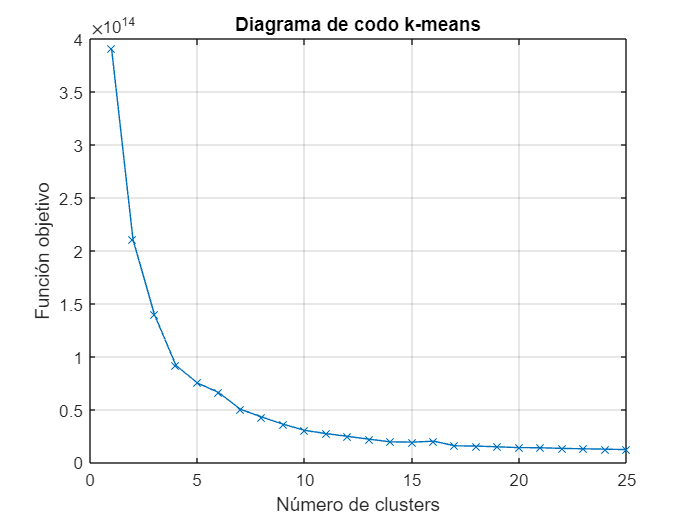

n = 25;
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

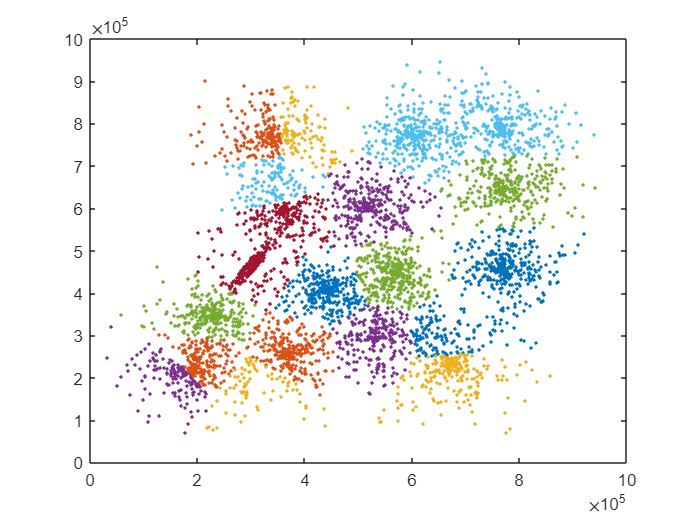


k=20;
idx = kmeans(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


fprintf("kmeans");

kmeans

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 4.5031e+04

SSB = 2.5450e+05

WB = 3.5388

SIL = 0.6073


fprintf("kmedoids");

kmedoids

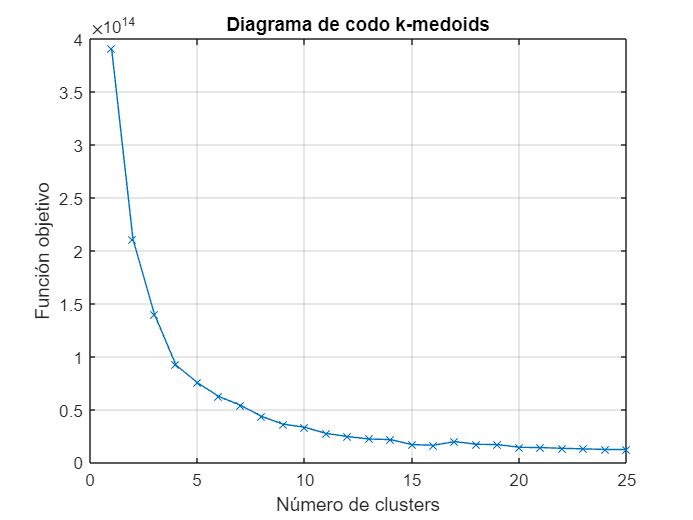


% Diagrama de codo kmedoids
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

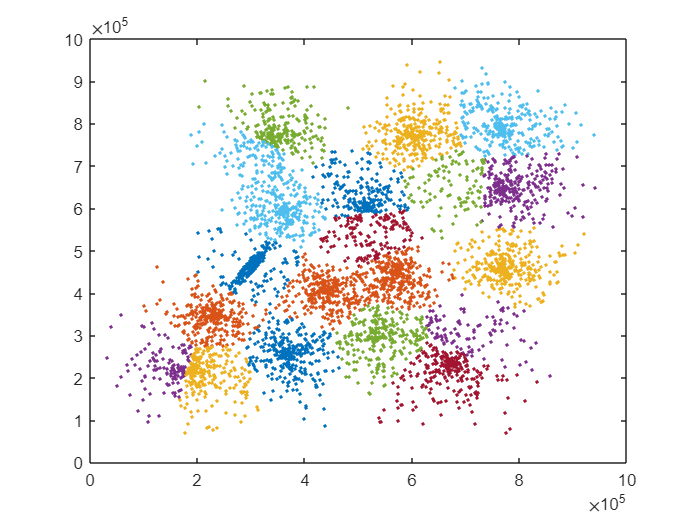


k=20;
idx = kmedoids(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 4.5200e+04

SSB = 2.5455e+05

WB = 3.5513

SIL = 0.6038


fprintf("DBSCAN");

DBSCAN


ep = clusterDBSCAN.estimateEpsilon(X,2,10)

ep = 1.7451e+04

idx = dbscan(X,ep,10);
k1 = max(idx);
idx(idx==-1)= k1+1;
idx(idx==0)= k1+2;
k0 = min(idx)

k0 = 1

k1 = max(idx)

k1 = 17

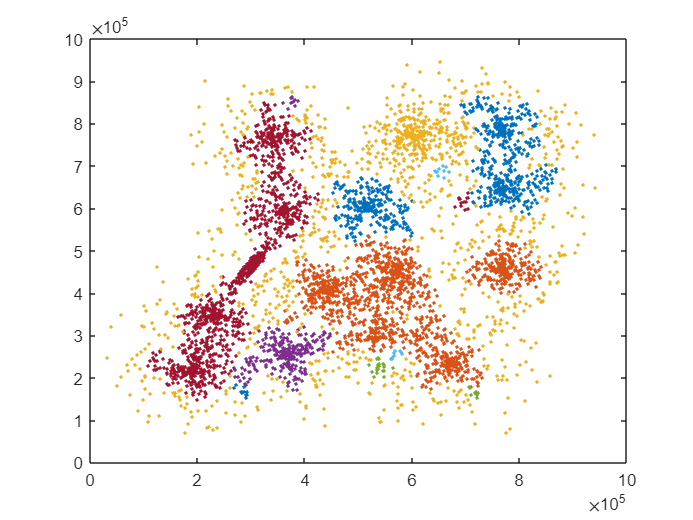


figure;
for i=k0:k1
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 1.3998e+05

SSB = 1.8389e+05

WB = 12.9408

SIL = -0.3075